data = readtable("C:\Users\Dell\Documents\MATLAB\CC GENERAL.csv",VariableNamingRule="preserve");
head(data, 5);

     CUST_ID      BALANCE    BALANCE_FREQUENCY    PURCHASES    ONEOFF_PURCHASES    INSTALLMENTS_PURCHASES    CASH_ADVANCE    PURCHASES_FREQUENCY    ONEOFF_PURCHASES_FREQUENCY    PURCHASES_INSTALLMENTS_FREQUENCY    CASH_ADVANCE_FREQUENCY    CASH_ADVANCE_TRX    PURCHASES_TRX    CREDIT_LIMIT    PAYMENTS    MINIMUM_PAYMENTS    PRC_FULL_PAYMENT    TENURE
    __________    _______    _________________    _________    ________________    ______________________    ____________    ___________________    __________________________    ___

summary(data)


data: 8950×18 table

Variables:

    CUST_ID: cell array of character vectors
    BALANCE: double
    BALANCE_FREQUENCY: double
    PURCHASES: double
    ONEOFF_PURCHASES: double
    INSTALLMENTS_PURCHASES: double
    CASH_ADVANCE: double
    PURCHASES_FREQUENCY: double
    ONEOFF_PURCHASES_FREQUENCY: double
    PURCHASES_INSTALLMENTS_FREQUENCY: double
    CASH_ADVANCE_FREQUENCY: double
    CASH_ADVANCE_TRX: double
    PURCHASES_TRX: double
    CREDIT_LIMIT: double
    PAYMENTS: double
    MINIMUM_PAYMENTS: double
    PRC_FULL_PAYMENT: double
    TENURE: double

Statistics for applicable variables:

                                        NumMissing  

%% Remove Customer ID (not useful for clustering)
data.CUST_ID = [];
%% Handle missing values (replace NaN with column mean)
for i = 1:width(data)
    if isnumeric(data{:,i})
        col = data{:,i};
        col(isnan(col)) = mean(col, 'omitnan');
        data{:,i} = col;
    end
end

%% Avoid division by zero

% Replace zeros with small value
data.BALANCE(data.BALANCE == 0) = 1;
data.PURCHASES(data.PURCHASES == 0) = 1;
data.CREDIT_LIMIT(data.CREDIT_LIMIT == 0) = 1;

%% Create new financial behavior features

% Spending intensity
data.SpendingRatio = data.PURCHASES ./ data.CREDIT_LIMIT;

% Payment discipline
data.PaymentRatio = data.PAYMENTS ./ data.BALANCE;

% Cash dependency (risk indicator)
data.CashUsageRatio = data.CASH_ADVANCE ./ data.CREDIT_LIMIT;

% Installment behavior
data.InstallmentRatio = data.INSTALLMENTS_PURCHASES ./ data.PURCHASES;

% Transaction activity level
data.TransactionRate = data.PURCHASES_TRX ./ data.TENURE;

%% Fix NaN created from feature engineering
%% Replace Inf and NaN AFTER all features are created

data{:, :}(isinf(data{:, :})) = NaN;
data = fillmissing(data, 'constant', 0);

%% Select relevant features

selectedFeatures = {
    'BALANCE'
    'PURCHASES'
    'CASH_ADVANCE'
    'CREDIT_LIMIT'
    'PAYMENTS'
    'PRC_FULL_PAYMENT'
    'SpendingRatio'
    'PaymentRatio'
    'CashUsageRatio'
    'TransactionRate'
};

X = data{:, selectedFeatures};

%% Fix Inf and NaN values properly

% Replace Inf (division by zero) with NaN
data{:, :}(isinf(data{:, :})) = NaN;

% Replace NaN with 0 (safe for ratios)
data = fillmissing(data, 'constant', 0);

%% Normalize (Z-score)
X_norm = zscore(X);


%% Check normalized data
disp('Normalized Data Preview:')

Normalized Data Preview:


disp(X_norm(1:5,:))

   -0.7320   -0.4250   -0.4668   -0.9604   -0.5289   -0.5255   -0.3832   -0.0151   -0.1971   -0.5225
    0.7869   -0.4692    2.6055    0.6886    0.8186    0.2342   -0.6014   -0.0154    0.5293   -0.6022
    0.4471   -0.1078   -0.4668    0.8260   -0.3838   -0.5255   -0.3656   -0.0155   -0.1971   -0.1239
    0.0491    0.2319   -0.3686    0.8260   -0.5987   -0.5255   -0.1440   -0.0155   -0.1754   -0.5624
   -0.3588   -0.4622   -0.4668   -0.9054   -0.3643   -0.5255   -0.5712   -0.0155   -0.1971   -0.5624




any(isnan(X_norm), 'all')

ans = logical
   0


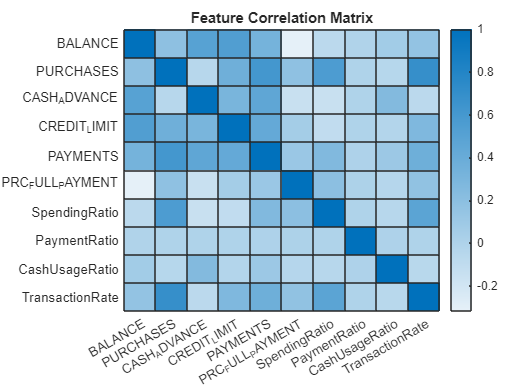

%Exploratory Data Analysis (EDA)
%% Correlation Heatmap

corrMatrix = corr(X_norm);

figure
heatmap(selectedFeatures, selectedFeatures, corrMatrix)
title('Feature Correlation Matrix')

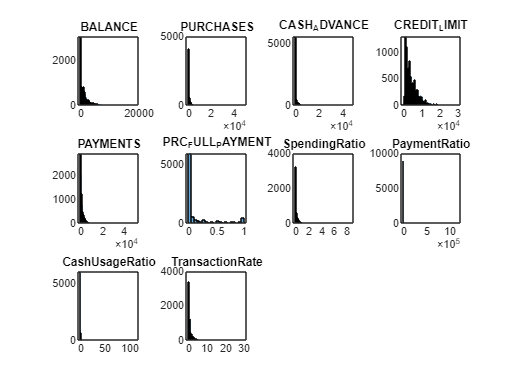

%%  Histograms (Feature Distribution)

figure
for i = 1:length(selectedFeatures)
    subplot(3,4,i)
    histogram(X(:,i))
    title(selectedFeatures{i})
end

% Recommended Preprocessing based on your histograms
%dataScaled = normalize(data); % Standardize to mean 0 and std 1
% Or apply log transform to highly skewed columns
%data.BALANCE = log1p(data.BALANCE);

## dd 

## 1. Interpretation of the Feature Correlation Matrix

This heatmap tells us how your financial variables "move" in relation to one another. For Vantage Ledger Group, this helps identify redundant information or hidden drivers of wealth.

- **Strong Positive Correlations (Darker Blue):**

- **PURCHASES vs. TransactionRate/SpendingRatio:** There is a notable correlation here. High-volume purchasers tend to have higher transaction rates. This suggests that "Spending Velocity" is a key metric for your personas.

- **BALANCE vs. PAYMENTS/CASH_ADVANCE:** A logical link—higher balances often lead to higher minimum payments or higher reliance on cash advances.

- **Weak/Negative Correlations (Light Blue/White):**

- **PRC_FULL_PAYMENT vs. BALANCE:** Notice the very light color here. This suggests that people with high balances are *not* necessarily the ones paying in full. This is a critical distinction for your archetypes (e.g., "The Revolver" vs. "The Transactor").

- **Asset Independence:** Many features show low correlation with each other (near 0). This is actually **excellent news** for clustering; it means your features are "orthogonal" and provide unique information, which will help K-Means or GMM find distinct boundaries.

## 2. Interpretation of the Feature Distributions (Histograms)

These charts show the "shape" of your data. For High-Net-Worth (HNW) archetyping, the **skewness** is the most important takeaway.

- **Heavy Right-Skewness (The "Long Tail"):**

- Almost every variable (BALANCE, PURCHASES, PAYMENTS) follows a power-law distribution. Most users are at the low end, while a tiny "Elite" group is far to the right.

- **Actionable Insight:** In MATLAB, you should consider applying a **Log Transformation** or **Standardization (Z-score)** before clustering. If you don't, the extreme outliers (the very wealthy) will pull the cluster centers too far, potentially masking the subtle differences between "The Liquidity-Heavy Professional" and "The Aggressive Reinvestor."

- **Bimodal Behavior (PRC_FULL_PAYMENT):**

- This histogram is unique. You see a peak at 0 and a smaller peak at 1. This indicates a binary behavior in the population: people either almost never pay in full, or they always do. This will likely be one of the strongest "Fingerprint" traits for your personas.

- **Sparsity in Ratios:**

- Variables like `PaymentRatio` and `CashUsageRatio` are very concentrated near zero. This suggests that extreme financial behaviors are rare, making those who exhibit them (the outliers) highly valuable targets for a boutique CFO firm.